%% 抛物线绘图（匹配黑板公式 + 输出xyz点云供SolidWorks导入）
clear; clc; close all;

% -------------------- 1. 定义抛物线参数（使用黑板公式） --------------------
% 黑板公式：P(φ) = (2d/(1-cosφ)) * [cosφ, sinφ]^T
d = 1;                  % 焦距（焦点到准线的距离）
phi = linspace(-pi/2+0.01, 3*pi/2-0.01, 500); % 参数范围，避免奇点
r = 2*d ./ (1 - cos(phi)); % 极径
x0 = r .* cos(phi);      % 原始抛物线（开口向右，焦点在原点）
y0 = r .* sin(phi);

% -------------------- 添加旋转矩阵 --------------------
theta = 30 * pi/180;    % 旋转角度30°转换为弧度
R = [cos(theta), -sin(theta);
     sin(theta), cos(theta)];  % 2D旋转矩阵

% 对抛物线上的所有点进行旋转变换
points_2d = [x0; y0];
rotated_points_2d = R * points_2d;
x = rotated_points_2d(1, :);
y = rotated_points_2d(2, :);
z = zeros(size(x));     % 给SolidWorks的z坐标（平面曲线，设为0）

% -------------------- 保存xyz数据到txt文件（SolidWorks可直接导入） --------------------
% 格式：每行 x y z，用空格分隔
filename = 'parabola_rotated_30deg.txt';
fid = fopen(filename, 'w');
if fid == -1
    error('无法创建文件，请检查权限');
end
% 写入所有点
for i = 1:length(x)
    fprintf(fid, '%.6f %.6f %.6f\n', x(i), y(i), z(i));
end
fclose(fid);
disp(['点云已保存为：' fullfile(pwd, filename)]);

点云已保存为：D:\HuaweiMoveData\Users\dyl123456\Desktop\parabola_rotated_30deg.txt


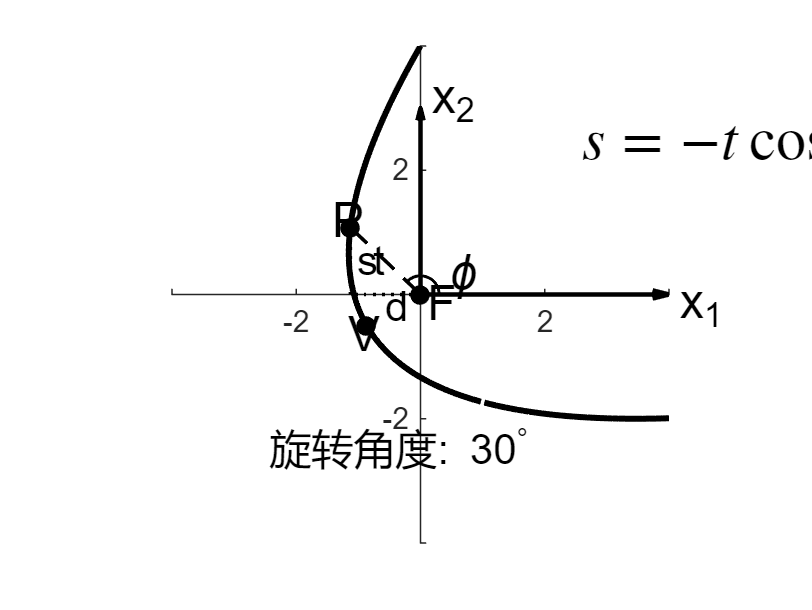


% -------------------- 2. 绘图基础设置（保留你的标注逻辑） --------------------
figure('Color','w'); hold on; axis equal;
grid off; box off;
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin'); % 坐标轴交于原点

% 画坐标轴（带箭头）
quiver(0, 0, 4, 0, 0, 'k', 'LineWidth',1.5);       % x1轴
quiver(0, 0, 0, 3, 0, 'k', 'LineWidth',1.5);       % x2轴
text(4.1, -0.2, 'x_1', 'FontSize',16);
text(0.1, 3.1, 'x_2', 'FontSize',16);

% 画旋转后的抛物线
plot(x, y, 'k', 'LineWidth',2);

% 标记顶点V和焦点F
% 原始顶点在phi=0时，坐标为x0=-d, y0=0；旋转后坐标
V_original = [-d, 0];
V = (R * V_original')';  % 旋转后的顶点
F = [0, 0];              % 焦点（原点旋转后仍为原点）

plot(V(1), V(2), 'ko', 'MarkerFaceColor','k');
text(V(1)-0.3, V(2)-0.15, 'V', 'FontSize',16);

plot(F(1), F(2), 'ko', 'MarkerFaceColor','k');
text(F(1)+0.1, F(2)-0.15, 'F', 'FontSize',16);

% -------------------- 3. 取抛物线上一点P并标注所有量 --------------------
py_original = 1.5;
px_original = (1/(4*d)) * py_original^2 - d; % 对应标准方程的顶点式
P_original = [px_original; py_original];
P_rotated = R * P_original;
P = P_rotated';

% 标记P点
plot(P(1), P(2), 'ko', 'MarkerFaceColor','k');
text(P(1)-0.3, P(2)+0.1, 'P', 'FontSize',16);

% 画线段FP（长度为t）
plot([F(1), P(1)], [F(2), P(2)], 'k--', 'LineWidth',1.2);
t = norm(P - F);
mid_t = (F + P)/2;
text(mid_t(1)-0.2, mid_t(2), 't', 'FontSize',14);

% 画水平线段d（F到P的水平投影，沿x1轴）
plot([F(1), P(1)], [F(2), F(2)], 'k:', 'LineWidth',1.2);
d = P(1) - F(1);
mid_d = (F + [P(1), F(2)])/2;
text(mid_d(1), mid_d(2)-0.2, 'd', 'FontSize',14);

% 画竖直线段s（P到水平投影的垂直距离，沿x2轴）
plot([P(1), P(1)], [F(2), P(2)], 'k:', 'LineWidth',1.2);
s = P(2) - F(2);
mid_s = ([P(1), F(2)] + P)/2;
text(mid_s(1)+0.1, mid_s(2), 's', 'FontSize',14);

% 标注角度φ（FP与x1轴正方向的夹角）
phi = atan2(P(2)-F(2), P(1)-F(1));
r = 0.3;
arc_theta = linspace(0, phi, 50);
arc_x = F(1) + r*cos(arc_theta);
arc_y = F(2) + r*sin(arc_theta);
plot(arc_x, arc_y, 'k-', 'LineWidth',1);
text(F(1)+0.4, 0.3, '\phi', 'FontSize',16);

% -------------------- 添加旋转角度标注 --------------------
rotation_angle = 30;
text(-2.5, -2.5, ['旋转角度: ' num2str(rotation_angle) '^\circ'], 'FontSize',14);

% -------------------- 4. 标注黑板上的公式 --------------------
text(2.5, 2.5, '$s = -t\cos\phi$', 'Interpreter','latex', 'FontSize',20);

% -------------------- 5. 调整坐标轴范围 --------------------
xlim([-4, 4]);
ylim([-4, 4]);

hold off;